We define a function and, for reference, its two exact partial derivatives.

u = @(x,y) sin(x.*y-y);
dudx = @(x,y) y.*cos(x.*y-y);
dudy = @(x,y) (x-1).*cos(x.*y-y);

We use an equispaced grid and second order finite differences as implemented by `diffmat2`.

m = 80;  [x,Dx] = diffmat2(m,[0,2*pi]);
n = 60;  [y,Dy] = diffmat2(n,[1,3]);
[X,Y] = ndgrid(x,y);
U = u(X,Y);

Here we compare the exact $\partial u/\partial x$ with the finite-difference approximation.

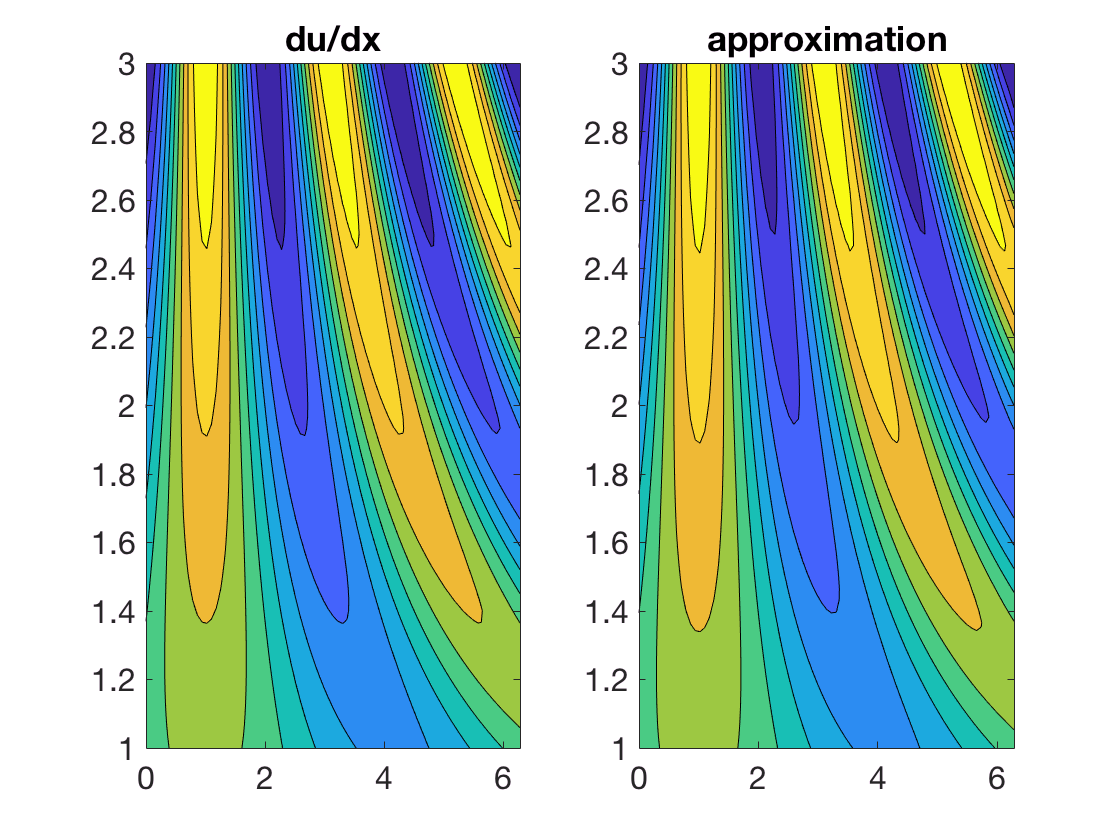

subplot(1,2,1)
contourf(X,Y,dudx(X,Y),10)
title('du/dx')     % ignore this line
subplot(1,2,2)
contourf(X,Y,Dx*U,10)
title('approximation')    % ignore this line

We now do the same for $\partial u/\partial y$,

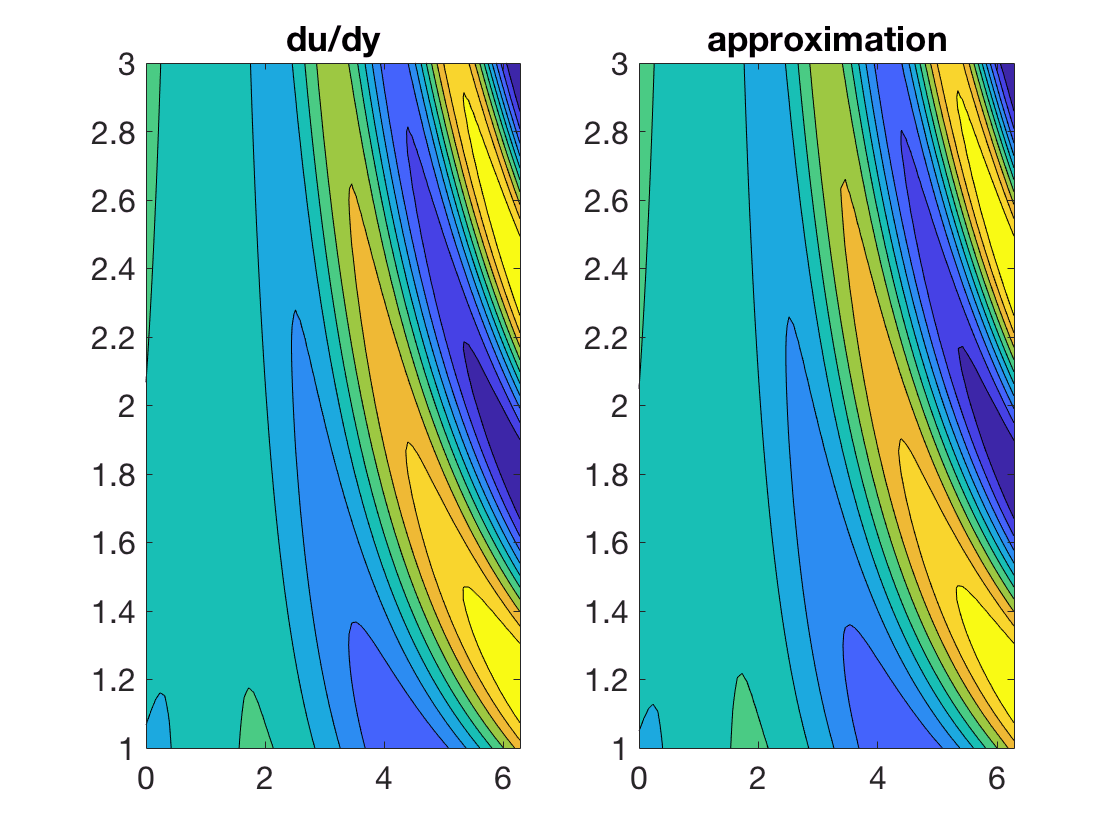

subplot(1,2,1)
contourf(X,Y,dudy(X,Y),10)
title('du/dy')    % ignore this line
subplot(1,2,2)
contourf(X,Y,U*Dy',10)
title('approximation')    % ignore this lineo

To the eye there is little difference to be seen, though we expect that the results probably have no more than 2-4 correct digits for these discretization sizes. 